% Find the Fourier transform of the function
syms x z pi;
f(x)=piecewise(x<-1,0,-1<=x<=-0.5,x+1,-0.5<x<0.5,1,0.5<=x<=1,-x+1,x>1,0)

$$f(x) = \left\{ \begin{array}{cl} 1 & \text{ if }x<\frac{1}{2}\\ 1-x & \text{ if }x\in \left[\frac{1}{2},1\right]\\ 0 & \text{ if }1<x \end{array}\right.$$

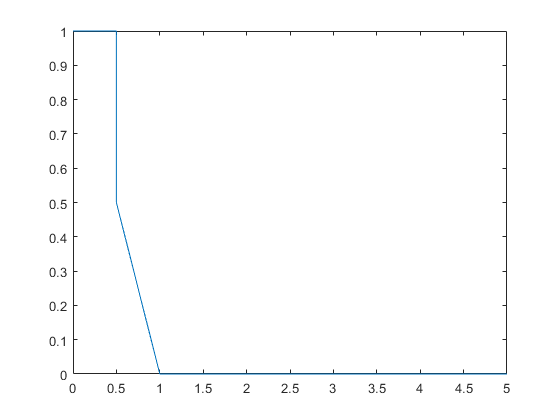

fplot(f)


syms u;
F(z)=1/sqrt(2*pi)*int(f(u)*exp(1i*z*u),u,-inf,+inf)

$$F(z) = \begin{array}{l} \left\{ \begin{array}{cl} -\frac{\sqrt{2}\,\left(\frac{\sigma_{7}\,\mathrm{i}}{z}-\sigma_{5}+\sigma_{6}\right)}{2\,\sqrt{\pi }} & \text{ if }\mathrm{imag}\left(z\right)<0\\ \frac{\sqrt{2}\,\left(\frac{\mathrm{i}}{z}\,\infty -\frac{\sigma_{7}\,\mathrm{i}}{z}+\sigma_{5}-\sigma_{6}\right)}{2\,\sqrt{\pi }} & \text{ if }0<\mathrm{imag}\left(z\right)\wedge 0<-z\,\mathrm{i}\\ -\frac{\sqrt{2}\,\left(\frac{\sigma_{7}\,\mathrm{i}}{z}-\frac{\left(\lim_{u\to -\infty }{\mathrm{e}}^{u\,z\,\mathrm{i}}\right)\,\mathrm{i}}{z}-\sigma_{5}+\sigma_{6}\right)}{2\,\sqrt{\pi }} & \text{ if }0<\mathrm{imag}\left(z\right)\wedge \neg 0<-z\,\mathrm{i}\\ -\frac{\sqrt{2}\,\left(\frac{-\sin\left(\frac{z}{2}\right)+\cos\left(\frac{z}{2}\right)\,\mathrm{i}}{z}-\sigma_{5}+\sigma_{6}\right)}{2\,\sqrt{\pi }} & \text{ if }z\neq 0\wedge \sigma_{4}\in \sigma_{1}\wedge \sigma_{3}\in \sigma_{2}\\ \frac{\sqrt{2}\,\left(\int_{-\infty }^{\frac{1}{2}}{\mathrm{e}}^{u\,z\,\mathrm{i}}\mathrm{d}u+\sigma_{5}-\sigma_{6}\right)}{2\,\sqrt{\pi }} & \text{ if }\left(z\in \mathbb{R}\vee \neg 0<-z\,\mathrm{i}\right)\wedge 0\leq \mathrm{imag}\left(z\right)\wedge \left(z\in \mathbb{R}\vee 0<-z\,\mathrm{i}\right)\wedge \left(z=0\vee \sigma_{4}\notin \sigma_{1}\vee \sigma_{3}\notin \sigma_{2}\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\left(-\frac{\pi }{2},\frac{\pi }{2}\right)\\ \sigma_{2}=\left[-\frac{\pi }{2},\frac{\pi }{2}\right]\\ \sigma_{3}=\text{angle}\left(-z\,\mathrm{i}\right)\\ \sigma_{4}=\text{angle}\left(z\,\mathrm{i}\right)\\ \sigma_{5}=\frac{\sigma_{7}\,\left(2\,\sigma_{7}\,\mathrm{i}+4\,\sin\left(\frac{z}{4}\right)\,{\mathrm{e}}^{\frac{z\,\mathrm{i}}{4}}-\mathrm{i}\right)}{2\,z}\\ \sigma_{6}=\frac{\sigma_{7}\,\left(2\,\sigma_{7}-2\right)}{2\,z^{2}}\\ \sigma_{7}={\mathrm{e}}^{\frac{z\,\mathrm{i}}{2}} \end{array}$$

F(z)=simplify(F(z))

$$F(z) = \begin{array}{l} \left\{ \begin{array}{cl} \mathrm{sign}\left(\frac{\mathrm{sign}\left(\frac{z^{2}}{\mathrm{sign}\left(z\right)}\right)}{z^{2}}\right)\,\mathrm{i}\,\infty & \text{ if }0<\mathrm{imag}\left(z\right)\wedge 0<-z\,\mathrm{i}\\ -\frac{2\,\sqrt{2}\,{\mathrm{e}}^{z\,\mathrm{i}}-2\,\sqrt{2}\,\sigma_{1}+\sqrt{2}\,z\,\sigma_{1}\,\mathrm{i}-2\,\sqrt{2}\,z\,\left(\lim_{u\to -\infty }{\mathrm{e}}^{u\,z\,\mathrm{i}}\right)\,\mathrm{i}}{\sigma_{2}} & \text{ if }0<\mathrm{imag}\left(z\right)\wedge \neg 0<-z\,\mathrm{i}\\ -\frac{\sqrt{2}\,\sigma_{1}\,\left(2\,\sigma_{1}-2+z\,\mathrm{i}\right)}{\sigma_{2}} & \text{ if }\mathrm{imag}\left(z\right)<0\vee \left(z\neq 0\wedge \text{angle}\left(z\,\mathrm{i}\right)\in \left(-\frac{\pi }{2},\frac{\pi }{2}\right)\wedge \text{angle}\left(-z\,\mathrm{i}\right)\in \left[-\frac{\pi }{2},\frac{\pi }{2}\right]\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{\frac{z\,\mathrm{i}}{2}}\\ \sigma_{2}=4\,z^{2}\,\sqrt{\pi } \end{array}$$

% (2^(1/2)*(4*cos(z/2) + 2*z*sin(z/2) - 8*cos(z/2)^2 + 4))/(4*z^2*pi^(1/2))
